# **Proyecto de ciencia de los datos**

## Universidad Autonoma del Estado de Mexico

## Centro Universitario UAEM Zumpango

## Ingenierieria en Computacion

## Ciencia de los Datos 2022-B

## Integrantes:

## Jose Armando Casillas Leyva

## Bryan Michael Trejo Garcia

## Profesor: Asdrúbal López Chau

## 25-10-2022

## Conjunto de Datos

El dataset WORLD UNIVERSITY RANKING 2022-2023 publicado por el Center for World University Ranking (CWUR ) el cual evalua a nivel global la calida de la eduacion, el empleo de exalumnos, la calidad de la facultad y el desempeño de investigacion.

Para ello se utilizan 7 indicadores conformado el 100% en la clasificacion de las universidades agrupandolos en 4 areas para clasificar las universidades del mundo.

Educacion:Basada en el exito acedemico de los ex-alumnos en relacion con las disticiones academicas obtenidas por los mismos. Ocupando el 25% de la escala.

Empleabilidad: Basado en el exito profesional de los ex alumnos de cada universidad. Relacionado a la ocupacion de altos puestos en empresas. Contribuyendo con el 25%.

Profesorado: Medido por los profesores que han obtenido una prestigiosa distincion, ocupando el 10%.

Investigacion: 

- Trabajos de investigacion 10%.

- Publicacion en revistas de primer nivel 10%.

- Articulos de investigacion publicados en revistas de gran influencia 10%

- Numero de articulos citados 10%.

## Preguntas

¿Estados unidos es el mejor pais para realizar una carrera universitaria?

¿Cual es el puntaje promedio del estudio?

¿Cual es el pais que predomina mas en el ranking de universidades?

¿Influye el pais para el nivel de estudio profecional?

## Analisis Exploratorios

### Carga de datos

M = readtable('datos2.csv');

head(M,2000)

ans = 2000×9 table
    WorldRank                   Institution                        Location         NationalRank    EducationRank    EmployabilityRank    FacultyRank    ResearchRank    Score
    _________    _________________________________________    __________________    ____________    _____________    _________________    ___________    ____________    _____

        1        {'Harvard University'                   }    {'USA'           }          1               1                   1                 1              1          100 
        2        {'Massachusetts Institute of Technology'}    {'USA'           }          2               4                  12                 2    

filename = "datos2.csv";
Rs = readmatrix(filename) % Lectura de datos numericos del .csv

Rs = 1.0e+03 *

    0.0010       NaN       NaN    0.0010    0.0010    0.0010    0.0010    0.0010    0.1000
    0.0020       NaN       NaN    0.0020    0.0040    0.0120    0.0020    0.0070    0.0967
    0.0030       NaN       NaN    0.0030    0.0110    0.0040    0.0030    0.0020    0.0951
    0.0040       NaN       NaN    0.0010    0.0030    0.0250    0.0040    0.0100    0.0941
    0.0050       NaN       NaN    0.0020    0.0070    0.0270    0.0090    0.0040    0.0933
    0.0060       NaN       NaN    0.0040    0.0050    0.0150    0.0060    0.0790    0.0926
    0.0070       NaN       NaN    0.0050    0.0080    0.0160    0.0210    0.0220    0.0920
    0.0080       NaN       NaN    0.0060    0.0120    0.0140    0.0100    0.0140    0.0915
    0.0090       NaN       NaN    0.0070    0.0140    0.0080    0.0410    0.0110    0.0911
    0.0100       NaN       NaN    0.0080    0.0020    0.1040    0.0070    0.0800    0.0907


### Media de los resultados de Scores

Sc = Rs(:, end);
media = mean(Sc);
msgmed = strcat("La media de los scores es: ", string(media));
msgmed

msgmed = "La media de los scores es: 71.5865"

### Moda de los resultados de Scores

moda = mode(Sc);

msgmod = "La moda de los scores es: 65.8"

msgmod = strcat("La moda de los scores es: ", string(moda));
msgmod

### Score minimo

smin = min(Sc);
msgsmin = strcat("El score minimo obtenido: ", string(smin));
msgsmin

msgsmin = "El score minimo obtenido: 65.7"

dats = [Sc(1), smin, media, moda]

dats =   100.0000   65.7000   71.5865   65.8000


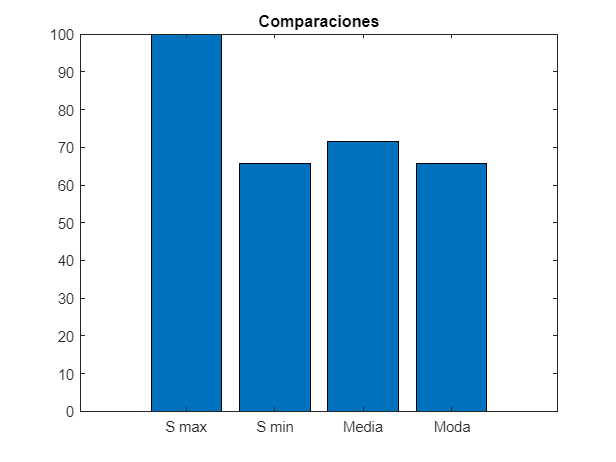

bar(dats)
set(gca,'XTickLabel',["S max","S min", "Media", "Moda"]);
title("Comparaciones")

## Análisis de los datos

### Paises

filename = "datos.csv";
Rs = readmatrix(filename) % Lectura de datos numericos del .csv

Rs = 1.0e+03 *

    0.0010       NaN       NaN    0.0010    0.0010    0.0010    0.0010    0.0010    0.1000
    0.0020       NaN       NaN    0.0020    0.0040    0.0120    0.0020    0.0070    0.0967
    0.0030       NaN       NaN    0.0030    0.0110    0.0040    0.0030    0.0020    0.0951
    0.0040       NaN       NaN    0.0010    0.0030    0.0250    0.0040    0.0100    0.0941
    0.0050       NaN       NaN    0.0020    0.0070    0.0270    0.0090    0.0040    0.0933
    0.0060       NaN       NaN    0.0040    0.0050    0.0150    0.0060    0.0790    0.0926
    0.0070       NaN       NaN    0.0050    0.0080    0.0160    0.0210    0.0220    0.0920
    0.0080       NaN       NaN    0.0060    0.0120    0.0140    0.0100    0.0140    0.0915
    0.0090       NaN       NaN    0.0070    0.0140    0.0080    0.0410    0.0110    0.0911
    0.0100       NaN       NaN    0.0080    0.0020    0.1040    0.0070    0.0800    0.0907


Sc = Rs(:, end);
Rp = readcell(filename);
P = Rp(2:end, 3);
P = categorical(P);
Paises10 = {'USA'; 'United Kingdom'; 'Japan'; 'France'; 'Canada'; 'Switzerland'; 'South Korea'; 'Denmark'; 'Sweden';'Germany'}

Paises10 = 10×1 cell array
    {'USA'           }
    {'United Kingdom'}
    {'Japan'         }
    {'France'        }
    {'Canada'        }
    {'Switzerland'   }
    {'South Korea'   }
    {'Denmark'       }
    {'Sweden'        }
    {'Germany'       }


save('10Paises.xlsx')

% USA
ContUSA = (P == 'USA');
ContUSA = P(ContUSA, :);
[TamUSA, ~] = size(ContUSA);

% UK
ContUK = (P == 'United Kingdom');
ContUK = P(ContUK, :);
[TamUK, ~] = size(ContUK);

% Japan
ContJap = (P == 'Japan');
ContJap = P(ContJap, :);
[TamJap, ~] = size(ContJap);

% France
ContFran = (P == 'France');
ContFran = P(ContFran, :);
[TamFran, ~] = size(ContFran);

% Canada
ContCan = (P == 'Canada');
ContCan = P(ContCan, :);
[TamCan, ~] = size(ContCan);

% Switzerland
ContSw = (P == 'Switzerland');
ContSw = P(ContSw, :);
[TamSw, ~] = size(ContSw);

% South Korea
ContSK = (P == 'South Korea');
ContSK = P(ContSK, :);
[TamSK, ~] = size(ContSK);

% Denmark
ContDen = (P == 'Denmark');
ContDen = P(ContDen, :);
[TamDen, ~] = size(ContDen);

% Sweden
ContSwe = (P == 'Sweden');
ContSwe = P(ContSwe, :);
[TamSwe, ~] = size(ContSwe);

% Germany
ContGer = (P == 'Germany');
ContGer = P(ContGer, :);
[TamGer, ~] = size(ContGer);

datosCont = [TamUSA; TamUK; TamJap; TamFran; TamCan; TamSw; TamSK; TamDen; TamSwe; TamGer]

datosCont =    335
    94
   118
    77
    42
    12
    57
     7
    20
    69


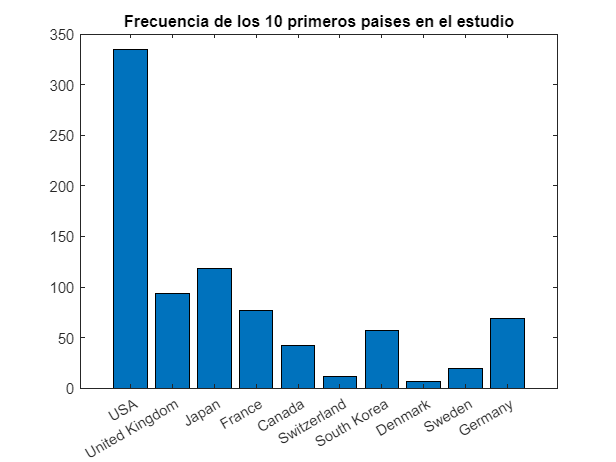

bar(datosCont)
set(gca,'XTickLabel',Paises10);
title("Frecuencia de los 10 primeros paises en el estudio")


% Pais con mayor recurrencia en el estudio
PaisM = find(max(datosCont));
msgsPM = strcat(Paises10(PaisM, :), " el pais con mayor frecuencia con ", string(max(datosCont)), " apariciones.");
msgsPM

msgsPM = "USA el pais con mayor frecuencia con 335 apariciones."

### Lista de Paises Completos y calificaciones promedio

Rp = readcell(filename);
P = Rp(2:end, 3);
P = categorical(P);
LP = unique(P, 'stable') % Obtenemos la lista de todos los paises en el orden prederterminado

LP = 96×1 categorical array
     USA 
     United Kingdom 
     Japan 
     France 
     Canada 
     Switzerland 
     South Korea 
     Denmark 
     Sweden 
     Germany 
     China 
     Australia 
     Israel 
     Netherlands 
     Norway 
     Singapore 
     Taiwan 
     Brazil 
     Italy 
     Belgium 
     Finland 
     Spain 
     Portugal 
     Russia 
     Austria 
     Czech Republic 
     Ireland 
     Saudi Arabia 
     South Africa 
     New Zealand 


msgsPM = strcat("La lista de paises contiene a ", string(size(LP)), " paises diferentes.");
msgsPM

msgsPM = 1×2 string array
    "La lista de paises contiene a 96 paises diferentes."    "La lista de paises contiene a 1 paises diferentes."



TamCont = [1:size(LP)];
TamCont= transpose(TamCont);
MediasP = [1:size(LP)];
MediasP= transpose(MediasP);
[tf, ~] = size(TamCont);
for i = 1:tf
    LCont = (P == LP(i,:));
    LInd = find(P == LP(i,:));
    LCont = P(LCont, :);
    LInd = Sc(LInd(:, :), :);
    [TamCont(i,:), ~] = size(LCont);
    MediasP(i,:) = mean(LInd);

end
TamCont

TamCont =    335
    94
   118
    77
    42
    12
    57
     7
    20
    69


MediasP

MediasP =    74.0188
   73.6777
   70.1347
   72.3351
   73.6476
   78.0167
   71.3807
   76.4429
   73.6400
   74.4348


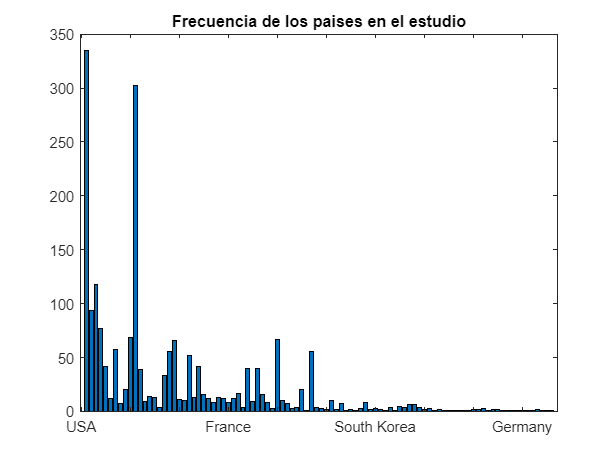

bar(TamCont)
set(gca, 'XTickLabel',LP);
title("Frecuencia de los paises en el estudio")

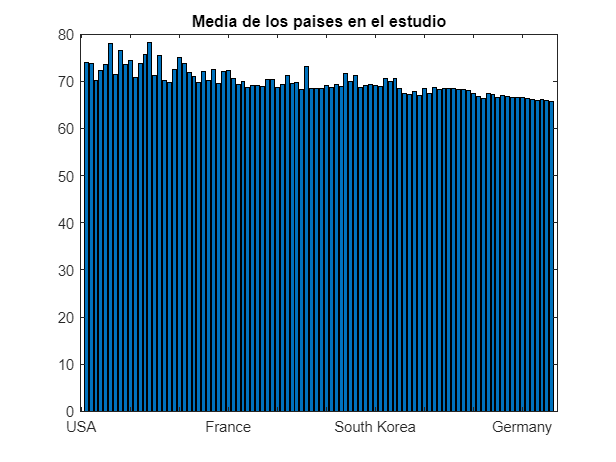

bar(MediasP)
set(gca,'XTickLabel',LP);
title("Media de los paises en el estudio")

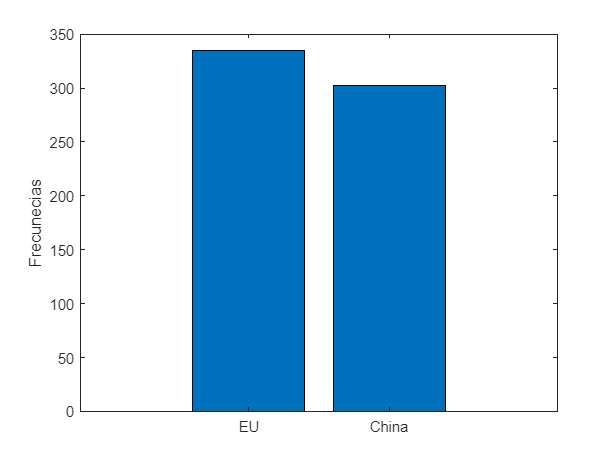

bar([TamCont(1),TamCont(11)])
set(gca,'XTickLabel',["EU", "China"]);
ylabel("Frecunecias")

###  Chi2

Ajuste a la distribucion 'Rayleigh'

dist = fitdist(TamCont, 'Rayleigh') %% Devuelve un objeto de distribucion de probabilidad con los intervalos de confianza

dist =   RayleighDistribution

  Rayleigh distribution
    B = 37.6037   [34.1893, 41.7819]


%histfit(TamCont)
% El histograma muestra que tiene una moda ajustandose a la distribucion
%qqplot(TamCont,dist)
% Gráfico cuantil-cuantil de los cuantiles de los datos de muestra xfrente a los valores cuantiles teóricos de la distribución ajustada.
% Ho: Estados unidos no es el mejor pais para realizar estudios
% universitarios
[h, p, std] = chi2gof(TamCont, 'CDF', dist) %% h=0: no se rechaza la hipotesis nula y h=1: se rechaza, los datos se ajustam o no a la dsitribucion de probabilidad

h = 1

p = 2.8358e-23

std = struct with fields:
    chi2stat: 98.7701
          df: 1
       edges: [1.0000 34.4000 67.8000 335.0000]
           O: [79 11 6]
           E: [32.8245 44.2800 18.8955]


% O: Lo observado, Vector de conteos observados para cada contenedor.
% E: Lo esperado, Vector de conteos esperados para cada contenedor.
% chi2stat— Valor de la estadística de prueba.
% df— Grados de libertad de la prueba.
% edges— Vector de bordes de contenedores después de la agrupación.

.

## Hallazgos

El pais con mas universidades incluidas en el estudio es Estados Unidos con 335 Universidades, mediante este resultado se deduce que el pais con mayor calidad en su educacion / mediante su frecuencia en el estudio.

La media de los puntajes obtenidos del estudio es 71.59 dados la cantidad de universidades y sus puntajes en el estudio.

Dada las frecuencias en el estudio de los paises, se deduce que el pais con mayor calidad en estudios universitarios es Estados Unidos. Y mediante la prueba de chi2 la prueba de hipotesis concluye que si es la mejor pais en educacion universitaria. De de la prueba de hipotesis no tenemos pruebas suficientes para decir que la verdadera distribución es la misma que se afirma.

## Conclusiones

De acuerdo a los diversos analicis que se realizaron a este conjunto de datos se puede concluir que:

Estados Unidos es un amplio dominador en el estudio profecional a nivel publico pero mas en el sector privado ya que consta de la mejor universidad en todo el mundo 

Asi de la misma manera es el que mayor cantidad de escuelas tiene en este ranking tanto publicas como privadas 

En segundo lugar tenemos el continente Europeo el cual tambien cuenta con nivel de estudio profecional superior 

Tambien nos damos cuenta que en LATAM el nivel esta muy por de bajo tanto de estados nidos como de la union Europea al solo contar con un poco menos del 5% del ranking

Una de las principales razones por el cual se da esta gran diferencia es el tema economico y politico en estos paises y continentes el cual es reflejado en la educacion 

De acuerdo a una lista realizada po rpromedio mexico ocupa el lugar 32 a nivel educacion profecional  con una media del 69.23

De igual manera EUA ocupa el primer lugar con una media de 74.04

Japon es otro pais en donde el nivel de educacion profecional es demaciado alto puesto que es reconocido por su estricta forma de vivir